# **HW5 Program Assignment**

**By: 105060012 張育菘**

## P5

A lowpass FIR filter is given by the specifications: $\omega_P$ = 0.3π, $\omega_S$ = 0.5π, and $A_S$ = 50 dB. 

Use the fir2 function to obtain a minimum length linearphase filter. Use the appropriate window function in the fir2 function. Provide a plot similar to Figure 10.12. 

Ans. 

$A_S$ = 50 dB $\longrightarrow$ choose Hamming window


$$\Delta \omega =\omega_S -\omega_P =0\ldotp 2\pi \ge 6\ldotp 6\frac{\pi }{L}\longrightarrow \mathrm{choose}\;L=33,M=32$$


close all; clear;
fprintf('1\n');

1


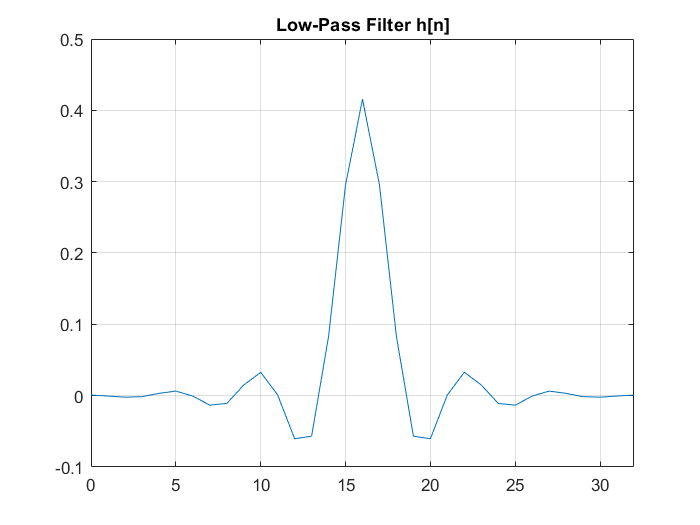


wp = 0.3*pi; ws = 0.5*pi; As = 50; M = 32;
deltas = 10^(-As/20);
wc = (wp + ws)/2;

om = linspace(0, pi, 1024);
n = 0:M;

h_lp = ideallp(wc,M);
[hlp_dtft, wlp_dtft] = freqz(h_lp, 1, om);
h = fir2(M, wlp_dtft/pi, abs(hlp_dtft), hamming(M+1));

[h_dtft, w_dtft] = freqz(h, 1, om);
len = length(h_dtft);
loc_ws = ceil((ws/pi)*length(h_dtft));
loc_wp = ceil((wp/pi)*length(h_dtft));

figure; plot(n, h); grid on;
title('Low-Pass Filter h[n]'); xlim([0 M]);

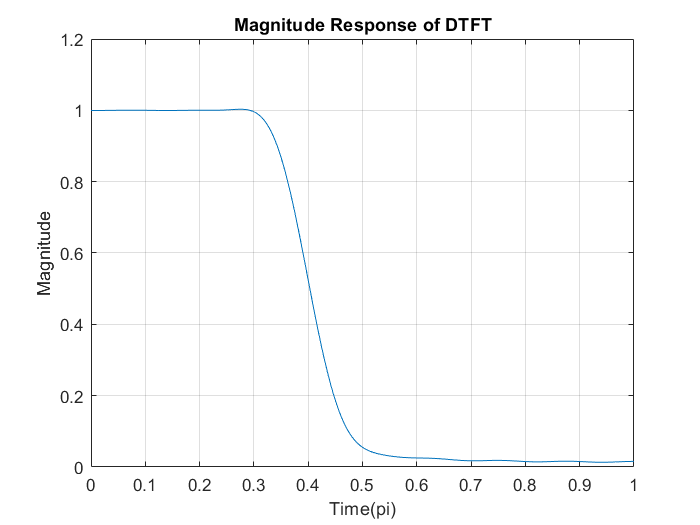

figure; plot(om/pi, abs(h_dtft)); grid on;
title('Magnitude Response of DTFT');
ylabel('Magnitude'); 
xlabel('Time(pi)'); 

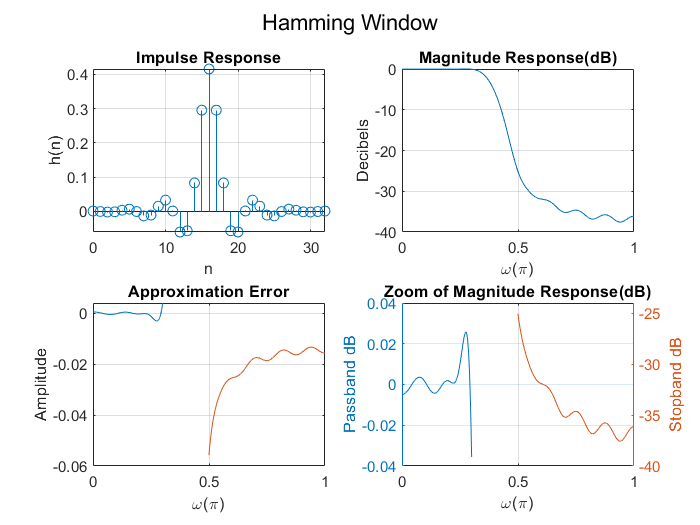


figure; sgtitle('Hamming Window');

subplot(2,2,1); stem(n, h); grid on;
title('Impulse Response');
xlabel('n'); ylabel('h(n)'); xlim([0 M]);

subplot(2,2,2); plot(w_dtft/pi,db(abs(h_dtft))); grid on
title('Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Decibels');

subplot(2,2,3); 
plot(w_dtft(1:loc_wp)/pi,1-abs(h_dtft(1:loc_wp))); 
hold on; grid on;
plot(w_dtft(loc_ws:len)/pi,0-abs(h_dtft(loc_ws:len))); 
hold on; grid on;
title('Approximation Error');
xlabel('\omega(\pi)'); ylabel('Amplitude'); xlim([0 1]);

subplot(2,2,4);
yyaxis left; plot(w_dtft(1:loc_wp)/pi,db(abs(h_dtft(1:loc_wp)))); 
hold on; grid on;
title('Zoom of Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Passband dB'); 
yyaxis right; plot(w_dtft(loc_ws:len)/pi,db(abs(h_dtft(loc_ws:len)))); 
hold on; grid on;
ylabel('Stopband dB'); xlim([0 1]);

## P6

Design a highpass FIR filter to satisfy the specifications: $\omega_S$ = 0.3π, $\omega_P$ = 0.5π, and $A_S$ = 50 dB. 

(a) Use Kaiser window to obtain a minimum length linear-phase filter. Provide a plot similar to Figure 10.12.

(???) Ideal high-pass filter (???)

close all; clear;
fprintf('6(a)\n');

6(a)


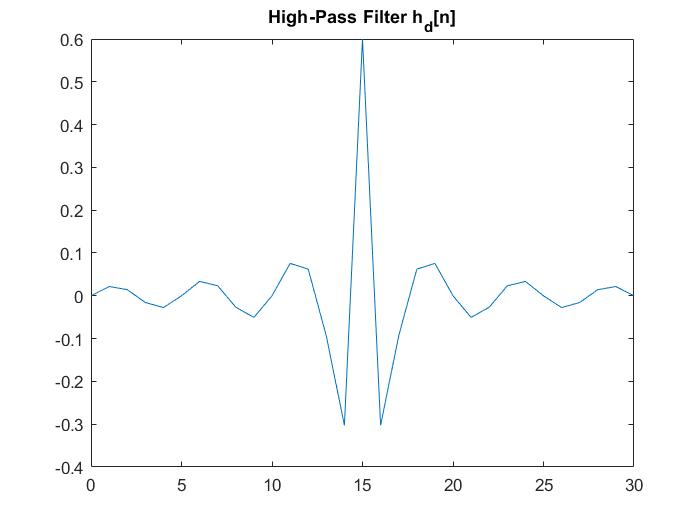


wp = 0.5*pi; ws = 0.3*pi; As = 50; A = As;
deltas = 10^(-As/20); 

Ap = -20*log10(1-deltas);

wc = (wp + ws)/2;
delta_om = abs(wp - ws);

if (A<21)
    beta = 0;
elseif (A>=21) && (A<=50)
    beta = 0.5842*(A-21)^(0.4)+0.07886*(A-21);
else
    beta = 0.1102*(A-8.7);
end

M = ceil((A-8)/(2.285*delta_om)); 
if mod(M, 2) == 1
    M = M + 1;
else 
    M = M;
end
L = M + 1;

n = 0:1:M; n_1 = (0:M)-M/2;
hd = sinc(n_1) - (wc*sinc(wc*(n_1)./pi)./pi);
% hd = sinc(pi.*n_1) - ideallp(wc, M)';
% hd = sinc(pi.*n_1) - ((wc/pi).*sinc(wc*n_1));
wn = kaiser(L,beta)';
h = hd.*wn;

[h_dtft,w_dtft] = freqz(h, 1);
len = length(h_dtft);
loc_ws = ceil((ws/pi)*length(h_dtft));
loc_wp = ceil((wp/pi)*length(h_dtft));

figure; plot(n, hd); 
title('High-Pass Filter h_d[n]'); xlim([0 M]);

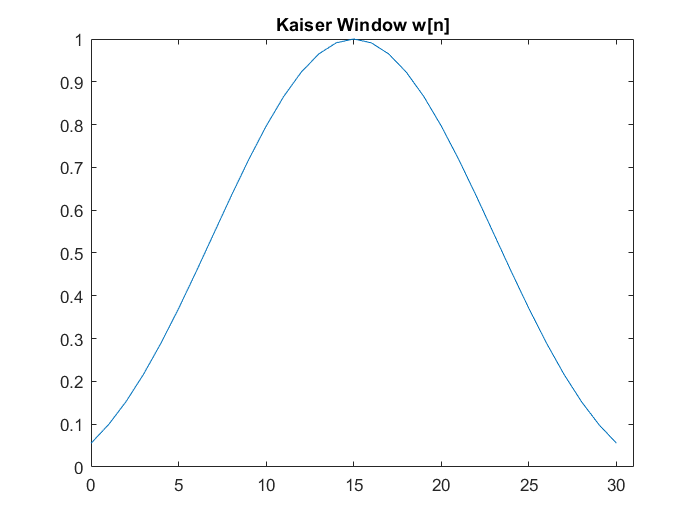

figure; plot(n, wn); 
title('Kaiser Window w[n]'); xlim([0 L]);

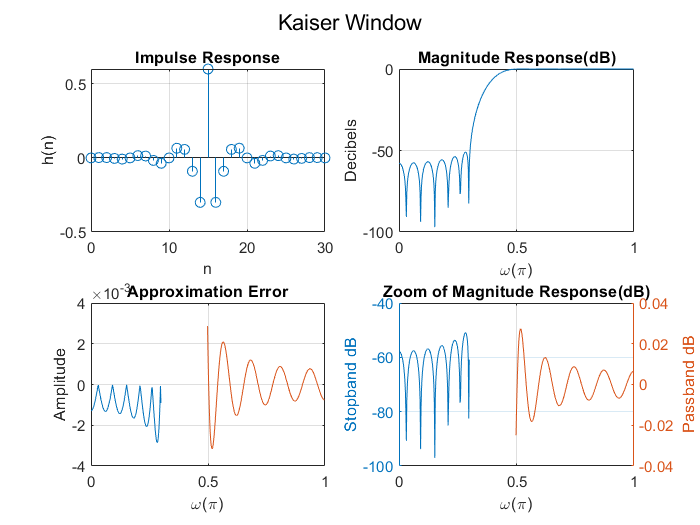


figure; sgtitle('Kaiser Window');

subplot(2,2,1); stem(n, h); grid on;
title('Impulse Response');
xlabel('n'); ylabel('h(n)'); xlim([0 M]);

subplot(2,2,2); plot(w_dtft/pi,db(abs(h_dtft))); grid on;
title('Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Decibels');

subplot(2,2,3); 
plot(w_dtft(1:loc_ws)/pi,0-abs(h_dtft(1:loc_ws))); 
hold on; grid on;
plot(w_dtft(loc_wp:len)/pi,1-abs(h_dtft(loc_wp:len))); 
hold on; grid on;
title('Approximation Error');
xlabel('\omega(\pi)'); ylabel('Amplitude'); xlim([0 1]);

subplot(2,2,4);
yyaxis left; plot(w_dtft(1:loc_ws)/pi,db(abs(h_dtft(1:loc_ws)))); 
hold on; grid on;
title('Zoom of Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Stopband dB'); 
yyaxis right; plot(w_dtft(loc_wp:len)/pi,db(abs(h_dtft(loc_wp:len)))); 
hold on; grid on;
ylabel('Passband dB'); xlim([0 1]);

(b) Repeat (a) using the fir1 function.

fprintf('6(b)\n');

6(b)


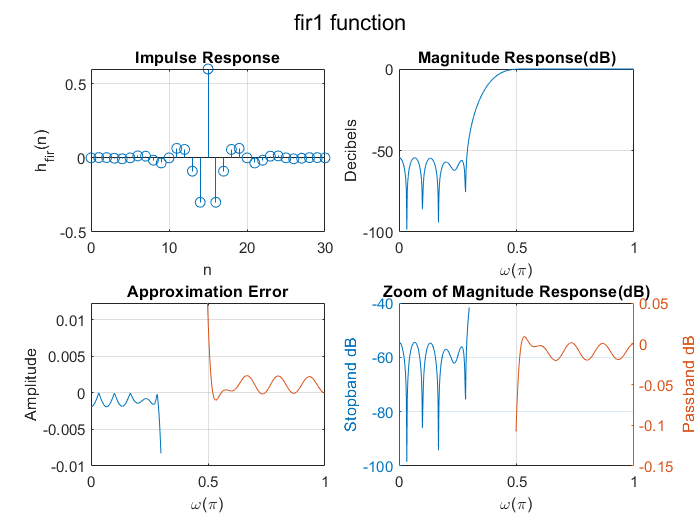


n = 0:1:M;
h_fir = fir1(M,wc/pi,'high'); 
[fir_dtft,wf_dtft] = freqz(h_fir);
lenf = length(fir_dtft);

figure; sgtitle('fir1 function'); 

subplot(2,2,1); stem(n, h_fir); grid on;
title('Impulse Response');
xlabel('n'); ylabel('h_f_i_r(n)'); xlim([0 M]);

subplot(2,2,2); plot(wf_dtft/pi,db(abs(fir_dtft))); grid on;
title('Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Decibels');

subplot(2,2,3); 
plot(wf_dtft(1:loc_ws)/pi,0-abs(fir_dtft(1:loc_ws))); 
hold on; grid on;
plot(wf_dtft(loc_wp:lenf)/pi,1-abs(fir_dtft(loc_wp:lenf))); 
hold on; grid on;
title('Approximation Error');
xlabel('\omega(\pi)'); ylabel('Amplitude'); xlim([0 1]);

subplot(2,2,4);
yyaxis left; plot(wf_dtft(1:loc_ws)/pi,db(abs(fir_dtft(1:loc_ws)))); 
hold on; grid on;
title('Zoom of Magnitude Response(dB)');
xlabel('\omega(\pi)'); ylabel('Stopband dB'); 
yyaxis right; plot(wf_dtft(loc_wp:lenf)/pi,db(abs(fir_dtft(loc_wp:lenf)))); 
hold on; grid on;
ylabel('Passband dB'); xlim([0 1]);

## P7

In this problem we reproduce Figures 10.4 and 10.5. For each of the following linear-phase FIR filters described by h[n], obtain impulse response, amplitude response, magnitude response, and pole-zero plots in one figure window. For frequency response plots use the interval −2π ≤ ω ≤ 2π. 

(a) Type-I filter: h[n] = {1, 2, 3, −2, 5, −2, 3, 2, 1}.

close all; clear;
fprintf('7(a): Type I\n');

7(a): Type I


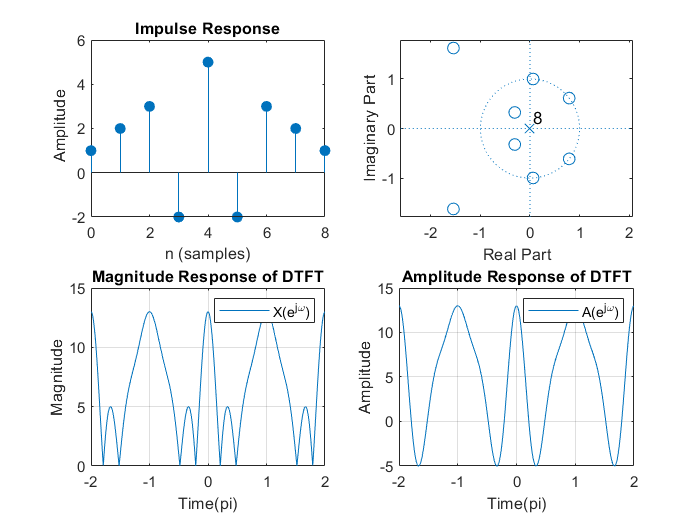


h1 = [1 2 3 -2 5 -2 3 2 1];
M = length(h1)-1; 
om = linspace(-2*pi, 2*pi, 2048);

h1_amp = h1((length(h1)+1)/2);
j = 1;
for i = ((length(h1)-1)/2):-1:1
    h1_amp = h1_amp + (2*h1(i)*cos(om.*j));
    j = j + 1;
end

h1_dtft = dtft12(h1, 0, om);

figure;

subplot(2,2,1); impz(h1, 1);

subplot(2,2,2); zplane(h1, 1);

subplot(2,2,3); plot(om/pi, abs(h1_dtft)); grid on;
title('Magnitude Response of DTFT');
legend('X(e^j^\omega)')
ylabel('Magnitude');
xlabel('Time(pi)');

subplot(2,2,4); plot(om/pi, h1_amp); grid on;
title('Amplitude Response of DTFT');
legend('A(e^j^\omega)')
ylabel('Amplitude');
xlabel('Time(pi)');

(b) Type-II filter: h[n] = {1, 2, 3, −2, −2, 3, 2, 1}. 

close all; clear;
fprintf('7(b): Type II\n');

7(b): Type II


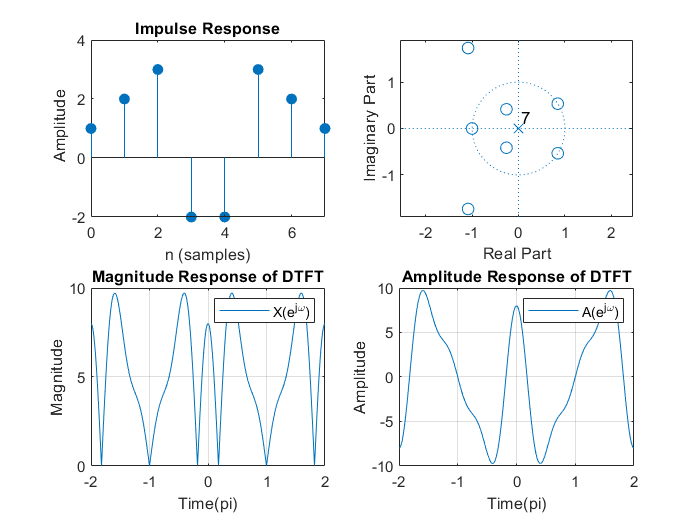


h2 = [1 2 3 -2 -2 3 2 1];
M = length(h2)-1; 
om = linspace(-2*pi, 2*pi, 2048);

h2_amp = 0;
j = 0;
for i = (length(h2)/2):-1:1
    h2_amp = h2_amp + (2*h2(i)*cos((om.*0.5)+(j.*om)));
    j = j + 1;
end

h2_dtft = dtft12(h2, 0, om);

figure;

subplot(2,2,1); impz(h2, 1);

subplot(2,2,2); zplane(h2, 1);

subplot(2,2,3); plot(om/pi, abs(h2_dtft)); grid on;
title('Magnitude Response of DTFT');
legend('X(e^j^\omega)')
ylabel('Magnitude');
xlabel('Time(pi)');

subplot(2,2,4); plot(om/pi, h2_amp); grid on;
title('Amplitude Response of DTFT');
legend('A(e^j^\omega)')
ylabel('Amplitude');
xlabel('Time(pi)');

(c) Type-III filter: h[n] = {1, 2, 3, −2, 0, 2, −3, −2, −1}.

close all; clear;
fprintf('7(c): Type III\n');

7(c): Type III


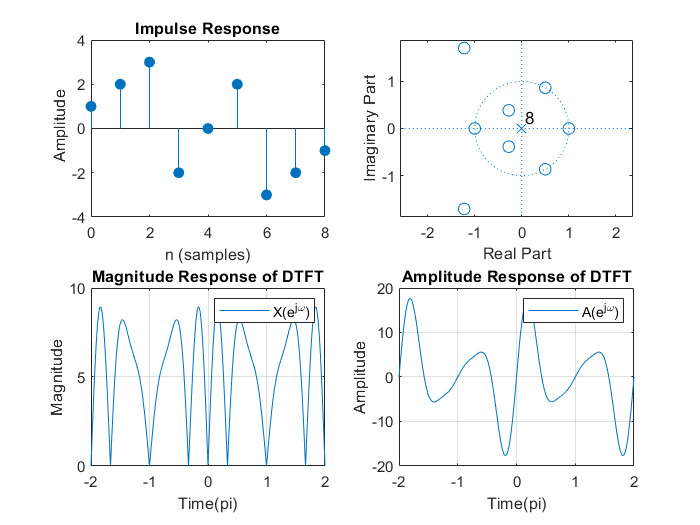


h3 = [1 2 3 -2 0 2 -3 -2 -1];
M = length(h3)-1; 
om = linspace(-2*pi, 2*pi, 2048);

c = zeros(1, M/2);
for i = 1:1:M/2
    c(i) = 2*h3((M/2)+1-i);
end

c_1 = zeros(1, (M/2));
c_1(M/2) = 2*c(M/2);
for i = ((M/2)-1):-1:2
    c_1(i) = 2*c(i) + c_1(i+1);
end
c_1(1) = 0.5*c_1(2) + c(1);

h3_amp = 0;
for i = 0:1:((M/2)-1)   
    h3_amp = h3_amp + (c_1(i+1)*cos(om.*i));
end
h3_amp = h3_amp .* sin(om);

h3_dtft = dtft12(h3, 0, om);

figure;

subplot(2,2,1); impz(h3, 1);

subplot(2,2,2); zplane(h3, 1);

subplot(2,2,3); plot(om/pi, abs(h3_dtft)); grid on;
title('Magnitude Response of DTFT');
legend('X(e^j^\omega)')
ylabel('Magnitude');
xlabel('Time(pi)');

subplot(2,2,4); plot(om/pi, h3_amp); grid on;
title('Amplitude Response of DTFT');
legend('A(e^j^\omega)')
ylabel('Amplitude');
xlabel('Time(pi)');

(d) Type-IV filter: h[n] = {1, 2, 3, −2, 2, −3, −2, −1 }. 

close all; clear;
fprintf('7(d): Type IV\n');

7(d): Type IV


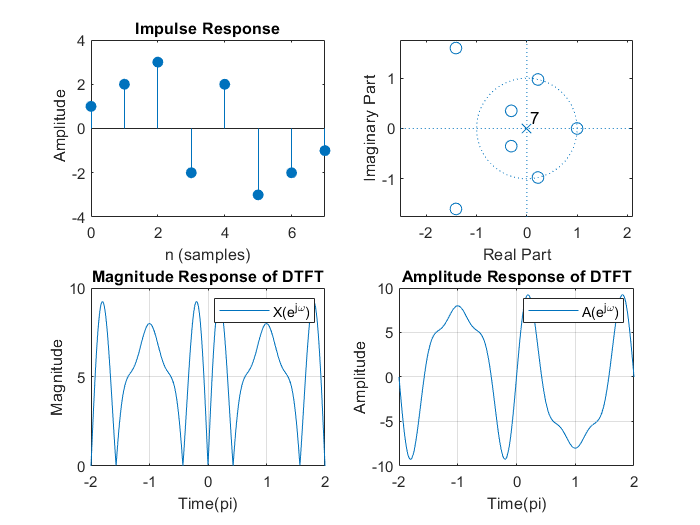


h4 = [1 2 3 -2 2 -3 -2 -1];
M = length(h4)-1; 
om = linspace(-2*pi, 2*pi, 2048);

d = zeros(1, (M+1)/2);
for i = 1:1:(M+1)/2
    d(i) = 2*h4(((M+1)/2)+1-i);
end

d_1 = zeros(1, (M+1)/2);
d_1((M+1)/2) = 2*d((M+1)/2);
for i = ((M-1)/2):-1:2
    d_1(i) = 2*d(i) + d_1(i+1);
end
d_1(1) = 0.5*d_1(2) + d(1);

h4_amp = 0;
for i = 0:1:(M-1)/2   
    h4_amp = h4_amp + (d_1(i+1)*cos(om.*i));
end
h4_amp = h4_amp .* sin(om./2);

h4_dtft = dtft12(h4, 0, om);

figure;

subplot(2,2,1); impz(h4, 1);

subplot(2,2,2); zplane(h4, 1);

subplot(2,2,3); plot(om/pi, abs(h4_dtft)); grid on;
title('Magnitude Response of DTFT');
legend('X(e^j^\omega)')
ylabel('Magnitude');
xlabel('Time(pi)');

subplot(2,2,4); plot(om/pi, h4_amp); grid on;
title('Amplitude Response of DTFT');
legend('A(e^j^\omega)')
ylabel('Amplitude');
xlabel('Time(pi)');

## P8

 Consider a Blackman window of length L = 21.

(a) Compute and plot the log-magnitude response in dB over −π ≤ ω ≤ π. In the plot measure and show the value of the peak of the first sidelobes.

close all; clear;
fprintf('8(a)\n');

8(a)


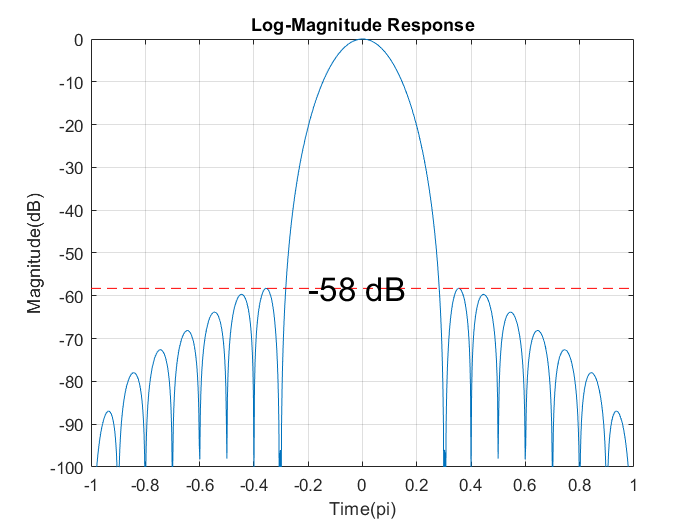


om = linspace(-pi, pi, 1024);
om_len = length(om);
L = 21; M = L - 1;
% blackm = 0.42 - 0.5*cos(2*pi*n/M) + 0.08*cos(4*pi*n/M);
blackm = blackman(L);
blackm_dtft = freqz(blackm, 1, om);
blackm_dtft = blackm_dtft./max(abs(blackm_dtft)); % nomorlize

[pks,locs] = findpeaks(20*log10(abs(blackm_dtft)),om);
sort_dtft = sort(pks,"descend");
sidelobe = sort_dtft(2); 
text_8a = [int2str(sidelobe), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_dtft))); grid on;
title('Log-Magnitude Response'); ylim([-100 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe,sidelobe],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe,text_8a, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Magnitude Response)", sidelobe);

Peak of the first sidelobes is -58.256904 dB (in Magnitude Response)

(b) Compute and plot the accumulated amplitude response in dB using the cumsum function. In the plot measure and show the value of the peak of the first sidelobe.

fprintf('8(b)\n');

8(b)


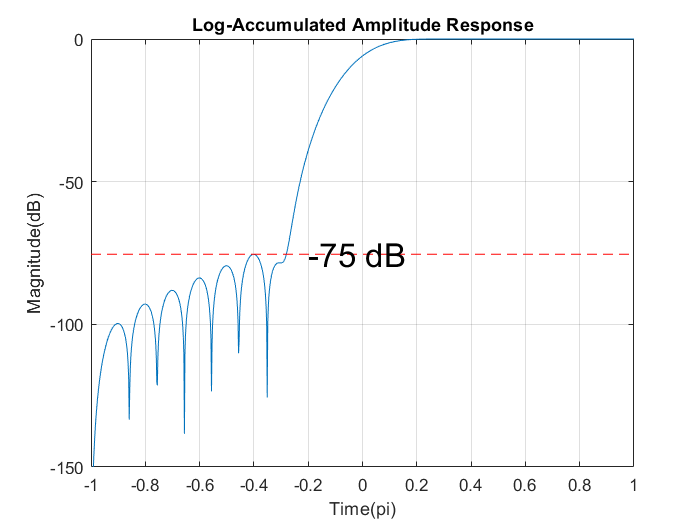


% Use Type I linear phase filter find amplitude response
blackm_amp = blackm((length(blackm)+1)/2);
j = 1;
for i = ((length(blackm)-1)/2):-1:1
    blackm_amp = blackm_amp + (2*blackm(i)*cos(om.*j));
    j = j + 1;
end

blackm_cum = cumsum(blackm_amp);
blackm_cum = blackm_cum ./ max(blackm_cum); % nomorlize

[pks,locs] = findpeaks(20*log10(abs(blackm_cum)),om);
sort_cum = sort(pks,"descend");
sidelobe_cum = sort_cum(5); 
text_8b = [int2str(sidelobe_cum), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_cum))); grid on;
title('Log-Accumulated Amplitude Response'); ylim([-150 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe_cum,sidelobe_cum],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe_cum,text_8b, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Amplitude Response)\n", sidelobe_cum);

Peak of the first sidelobes is -75.457425 dB (in Amplitude Response)


(c) Repeat (a) and (b) for L = 41.

close all; clear;
fprintf('8(c): L = 41\n');

8(c): L = 41


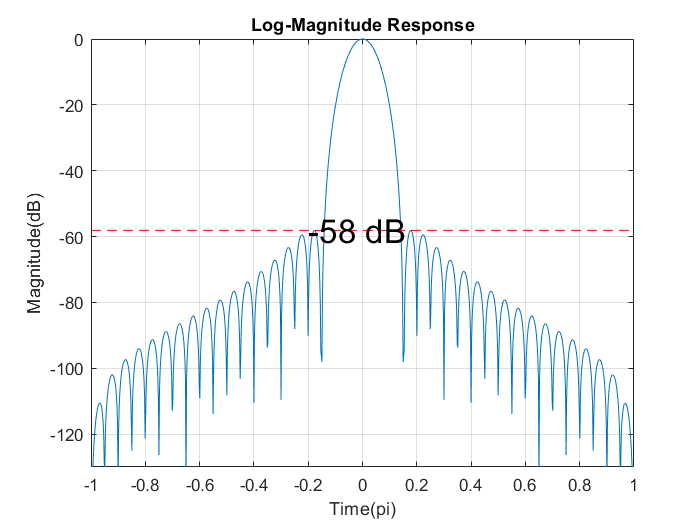


om = linspace(-pi, pi, 1024);
om_len = length(om);

L = 41;
blackm = blackman(L);
blackm_dtft = freqz(blackm, 1, om);
blackm_dtft = blackm_dtft./max(abs(blackm_dtft)); % nomorlize

% Use Type I linear phase filter find amplitude response
blackm_amp = blackm((length(blackm)+1)/2);
j = 1;
for i = ((length(blackm)-1)/2):-1:1
    blackm_amp = blackm_amp + (2*blackm(i)*cos(om.*j));
    j = j + 1;
end

% Find the accumulated amplitude response
blackm_cum = cumsum(blackm_amp);
blackm_cum = blackm_cum ./ max(blackm_cum); % nomorlize

[pks,locs] = findpeaks(20*log10(abs(blackm_dtft)),om);
sort_dtft = sort(pks,"descend");
sidelobe = sort_dtft(2); 
text_dtft = [int2str(sidelobe), ' dB'];

[pks,locs] = findpeaks(20*log10(abs(blackm_cum)),om);
sort_cum = sort(pks,"descend");
sidelobe_cum = sort_cum(10); 
text_cum = [int2str(sidelobe_cum), ' dB'];

figure; plot(om/pi, 20*log10(abs(blackm_dtft))); grid on;
title('Log-Magnitude Response'); ylim([-130 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe,sidelobe],'linestyle','--', 'color', 'r');
text(-0.2,sidelobe,text_dtft, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');

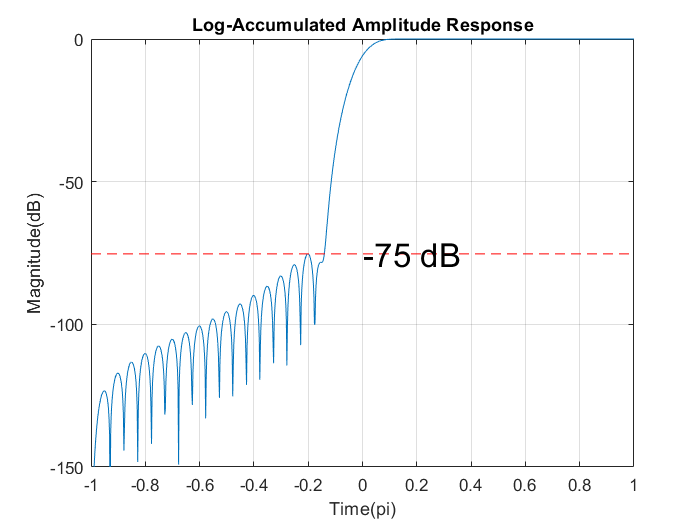


figure; plot(om/pi, 20*log10(abs(blackm_cum))); grid on;
title('Log-Accumulated Amplitude Response'); ylim([-150 0]);
line([om(1)/pi,om(om_len)/pi],[sidelobe_cum,sidelobe_cum],'linestyle','--', 'color', 'r');
text(0,sidelobe_cum,text_cum, 'Fontsize', 20);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("Peak of the first sidelobes is %f dB (in Magnitude Response)\n", sidelobe);

Peak of the first sidelobes is -58.119680 dB (in Magnitude Response)


fprintf("Peak of the first sidelobes is %f dB (in Amplitude Response)\n", sidelobe_cum);

Peak of the first sidelobes is -75.299049 dB (in Amplitude Response)


## P9

An ideal lowpass filter has a cutoff frequency of $\omega_c$ = 0.4π. We want to obtain a length L = 40 linear-phase FIR filter using the frequency-sampling method. 

(a) Let the sample at $\omega_c$ be equal to 0.5. Obtain the resulting impulse response h[n]. Plot the log-magnitude response in dB and determine the minimum stopband attenuation. 

Ans:

Stopband attenuation (dB): $A_S =-20\;{\mathrm{log}}_{10} \left(\delta_S \right)$


$$H_d \left\lbrack k\right\rbrack =H_d \left(e^{j\omega_c } \right)=H_d \left(e^{\mathrm{j2}\pi \frac{k}{L}} \right)=H_d \left\lbrack L\frac{\omega_c }{2\pi }\right\rbrack$$


close all; clear;
fprintf('9(a)\n');

9(a)


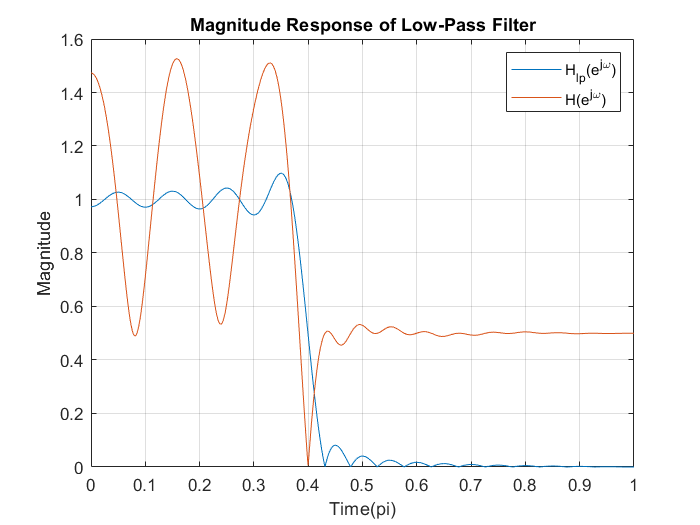


om = linspace(0, pi, 1024);

L = 40; M = L-1; wc = 0.4*pi; 
h_lp = ideallp(wc,L-1);
[hlp_dtft, wlp_dtft] = freqz(h_lp, 1, om);

h = h_lp; 
% the sample at wc be equal to 0.5
h(L*wc/(2*pi)) = 0.5;
[h_dtft, w_dtft] = freqz(h, 1, om);

figure; 
plot(wlp_dtft/pi, abs(hlp_dtft)); hold on; grid on;
plot(w_dtft/pi, abs(h_dtft)); hold off; grid on;
title('Magnitude Response of Low-Pass Filter');
legend('H_l_p(e^j^\omega)', 'H(e^j^\omega)');
ylabel('Magnitude');
xlabel('Time(pi)');

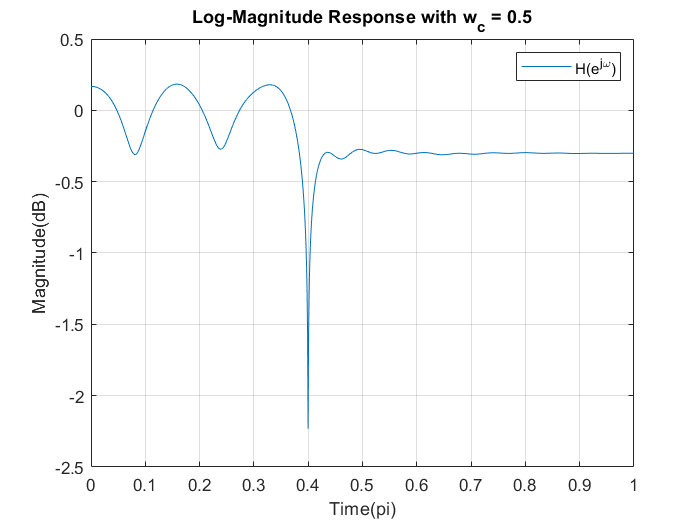


figure; plot(w_dtft/pi, log10(abs(h_dtft))); grid on;
title('Log-Magnitude Response with w_c = 0.5');
legend('H(e^j^\omega)');
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


[pks,locs] = findpeaks(log10(abs(h_dtft)),w_dtft);
index_min = 0;
for i = 1:1:length(pks)
    if pks(i) <= 0
        index_min = i;
        break;
    end
end

fprintf("The minimum stopband attenuation is %f dB", -20*pks(index_min));

The minimum stopband attenuation is 5.890004 dB

(b) Now vary the value of the sample at $\omega_c$ and find the largest minimum stopband attenuation. Obtain the resulting impulse response h[n] and plot the log-magnitude response in dB in the plot window of (a).

fprintf('9(b)\n');

9(b)


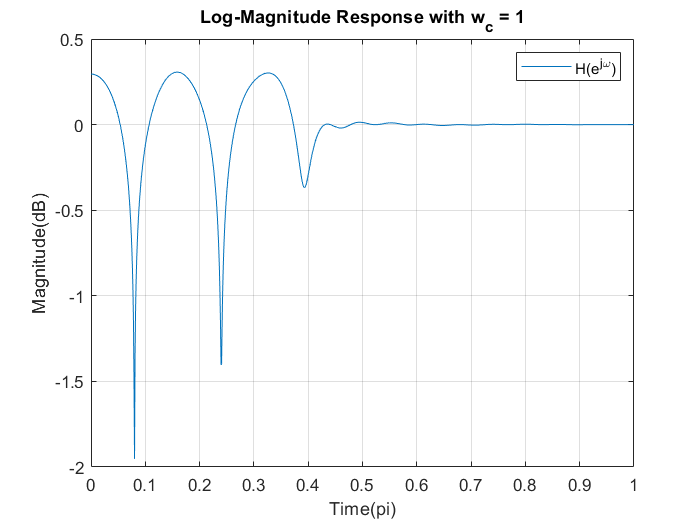


om = linspace(0, pi, 1024);

L = 40; wc = 0.4*pi;
h_lp = ideallp(wc,L-1);
[hlp_dtft, wlp_dtft] = freqz(h_lp, 1, om);

select_s = zeros(1, 3); % pk_value, wc_s, index
select_s(1) = -100;

for wc_s = 0: 0.05: 1
    hs = h_lp; 
    % the sample at wc be equal to wc_s
    hs(L*wc/(2*pi)) = wc_s;
    [hs_dtft, ws_dtft] = freqz(hs, 1, om);
    [pkss,locss] = findpeaks(log10(abs(hs_dtft)),ws_dtft);
    indexs_min = 1;
    for i = 1:1:length(pkss)
        if pkss(i) <= 0.01
            indexs_min = i;
            break;
        end
    end
    if select_s(1) < pkss(indexs_min)
        select_s(1) = pkss(indexs_min);
        select_s(2) = wc_s;
        select_s(3) = indexs_min;
    end
end

hs = h_lp; 
% the sample at wc be equal to wc_s
hs(L*wc/(2*pi)) = select_s(2);
[hs_dtft, ws_dtft] = freqz(hs, 1, om);

figure; plot(ws_dtft/pi, log10(abs(hs_dtft))); grid on;
title(['Log-Magnitude Response with w_c = ', num2str(select_s(2))]);
legend('H(e^j^\omega)');
ylabel('Magnitude(dB)');
xlabel('Time(pi)');

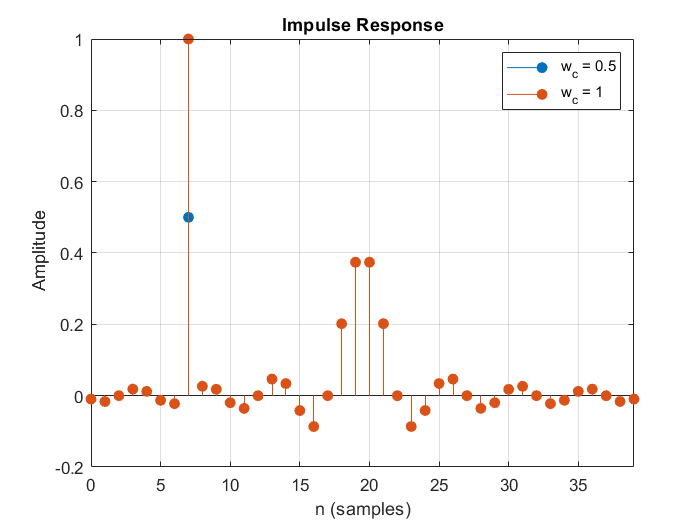


figure;
impz(h, 1); hold on; grid on;
impz(hs, 1); hold off; grid on;
title('Impulse Response');
legend(['w_c = 0.5'], ['w_c = ', num2str(select_s(2))]);

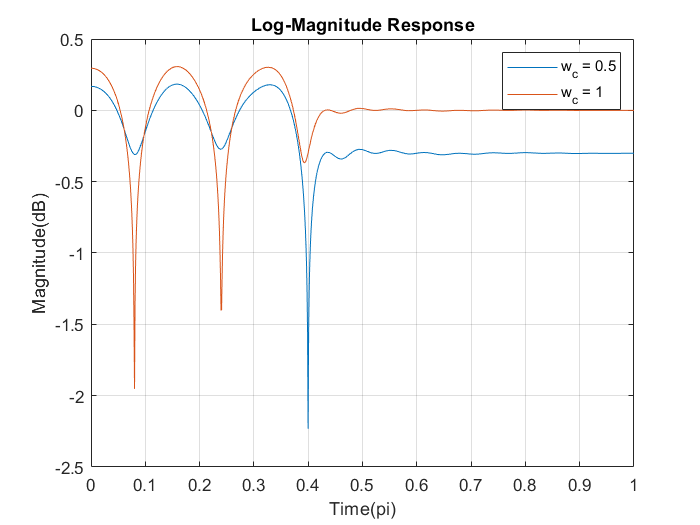


figure; 
plot(w_dtft/pi, log10(abs(h_dtft))); hold on; grid on;
plot(ws_dtft/pi, log10(abs(hs_dtft))); hold off; grid on;
title('Log-Magnitude Response');
legend(['w_c = 0.5'], ['w_c = ', num2str(select_s(2))]);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');


fprintf("The largest minimum stopband attenuation is %f dB", -20*select_s(1));

The largest minimum stopband attenuation is -0.059322 dB

(c) Compare your results with those obtained using the fir2 function (choose hamming window).

fprintf('9(c)\n');

9(c)



M1 = M + 1; % for M is even
h_fir = fir2(M1, w_dtft/pi, abs(h_dtft), hamming(M1+1));
hs_fir = fir2(M1, ws_dtft/pi, abs(hs_dtft), hamming(M1+1));

[h_fir_dtft, w_fir_dtft] = freqz(h_fir, 1, om);
[hs_fir_dtft, ws_fir_dtft] = freqz(hs_fir, 1, om);

[pks_fir,locs_fir] = findpeaks(log10(abs(h_fir_dtft)),w_fir_dtft);
index_min_fir = 0;
for i = 1:1:length(pks_fir)
    if pks_fir(i) <= 0
        index_min_fir = i;
        break;
    end
end

[pkss_fir,locss_fir] = findpeaks(log10(abs(hs_fir_dtft)),ws_fir_dtft);
indexs_min_fir = 1;
for i = 1:1:length(pkss_fir)
    if pkss_fir(i) <= 0.01
        indexs_min_fir = i;
        break;
    end
end

fprintf("By fir2, A_s (with w_c = 0.5) is %f dB", -20*pks_fir(index_min_fir));

By fir2, A_s (with w_c = 0.5) is 5.824315 dB

fprintf("By fir2, the largest A_s (with w_c = %.1f) is %f dB", select_s(2), -20*pkss_fir(indexs_min_fir));

By fir2, the largest A_s (with w_c = 1.0) is -0.097305 dB

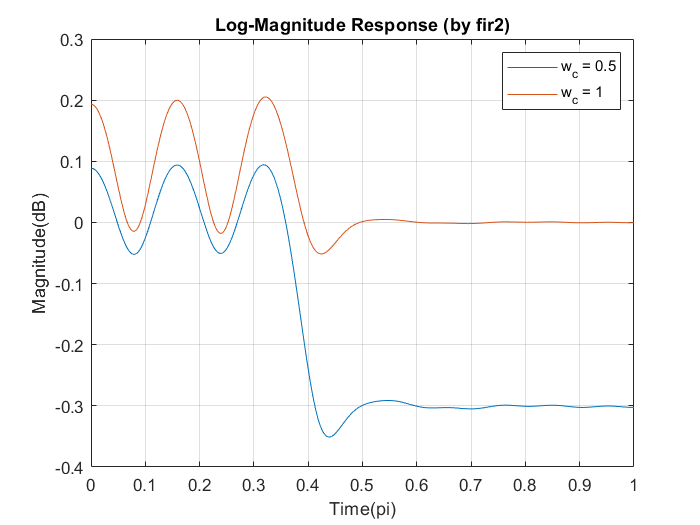


figure; 
plot(w_fir_dtft/pi, log10(abs(h_fir_dtft))); hold on; grid on;
plot(ws_fir_dtft/pi, log10(abs(hs_fir_dtft))); hold off; grid on;
title('Log-Magnitude Response (by fir2)');
legend(['w_c = 0.5'], ['w_c = ', num2str(select_s(2))]);
ylabel('Magnitude(dB)');
xlabel('Time(pi)');

We can find that the signals of Log-magnitude Response after processing by function fir2 are smoother than the original version, and the values of minimum stopband attenuation are quite similar to the results before using fir2.